# Guía 2 - Ejercicio 3

## Enunciado

Implemente una red con aprendizaje Backpropagation que aprenda la siguiente función 


$$f(x,y,z) = \sin(x)+\cos(y)+z$$


 donde $x,y\in (0 , 2\pi]$ y $z\in[-1, 1]$

Primero preparo los batches para entrenar

clear all
close all
heta = 0.0005;
w_0 = normrnd(0,0.1,[3 9]);%(rand([4 4])-0.5)*chico;
bias_0 = normrnd(0,0.1,[1 9]);%(rand([1 4])-0.5)*chico;
w_1 = normrnd(0,0.1,[9 15]);%(rand([4 8])-0.5)*chico;
bias_1 = normrnd(0,0.1,[1 15]);%(rand([1 8])-0.5)*chico;
w_2 = normrnd(0,0.1,[15 1]);%(rand([8 1])-0.5)*chico;
bias_2 = normrnd(0,0.1,[1 1]);%(rand([1 1])-0.5)*chico;
errores = [];

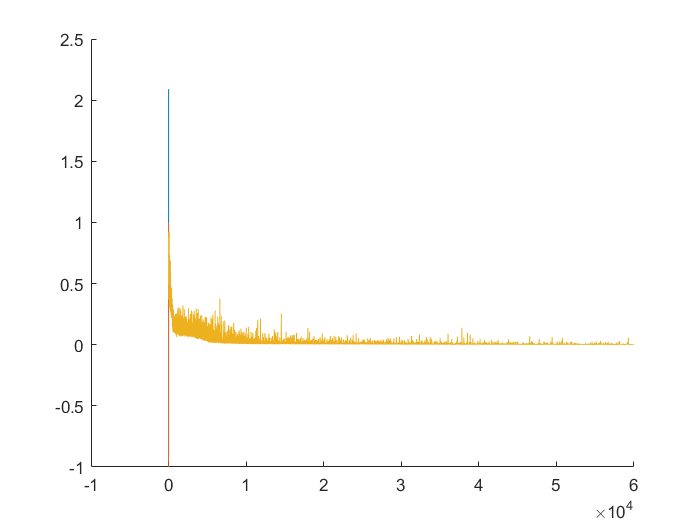

batch_size = 50;

%FORWARD
for epochs=1:10000
  x = rand([batch_size 1])*2*pi;
  y = rand([batch_size 1])*2*pi;
  z = rand([batch_size 1])*2 -1;
  dEdbias1 = 0;
  dEdw1 = 0;
  dEdbias0 = 0;
  dEdw0 = 0;
  dEdbias2 = 0;
  dEdw2 = 0;
  error_acumulado=0;
  for i=1:batch_size
      entrada = [x(i) y(i) z(i)];
      V1 = tanh(entrada*w_0+bias_0);
      V2 = tanh(V1*w_1+bias_1);
      %%salida = tanh(V2*w_2+bias_2)*4;
      salida = V2*w_2+bias_2;
      
      y_deseado = sin(entrada(1)) + cos(entrada(2)) + entrada(3);
      error = 0.5*(salida-y_deseado)^2;
      %BACK
      %%dEdbias2_partial = (salida-y_deseado)*(1-salida^2);
      dEdbias2_partial = (salida-y_deseado);
      
      dEdw2_partial = dEdbias2_partial*V2';
      dEdbias1_partial = dEdbias2_partial*w_2'.*(1-V2.^2);
      dEdw1_partial = V1'*dEdbias1_partial;
      dEdbias0_partial = (1-(V1).^2).*(w_1*dEdbias1_partial')';
      dEdw0_partial = dEdbias0_partial'*entrada;
      
      dEdbias2 = dEdbias2 + dEdbias2_partial;
      dEdw2 = dEdw2+dEdw2_partial;
      dEdbias1 = dEdbias1+dEdbias1_partial;
      dEdw1 = dEdw1+dEdw1_partial;
      dEdbias0 = dEdbias0 + dEdbias0_partial;
      dEdw0 = dEdw0+dEdw0_partial;
      error_acumulado = error_acumulado + error;

  end
  %UPDATE
  w_0 = w_0-heta*dEdw0';
  bias_0 = bias_0-heta*dEdbias0;
  w_1 = w_1-heta*dEdw1;
  bias_1 = bias_1-heta*dEdbias1;
  bias_2 = bias_2-heta*dEdbias2;
  w_2 = w_2-heta*dEdw2;

  errores = [errores error_acumulado];

end
plot(errores/batch_size)

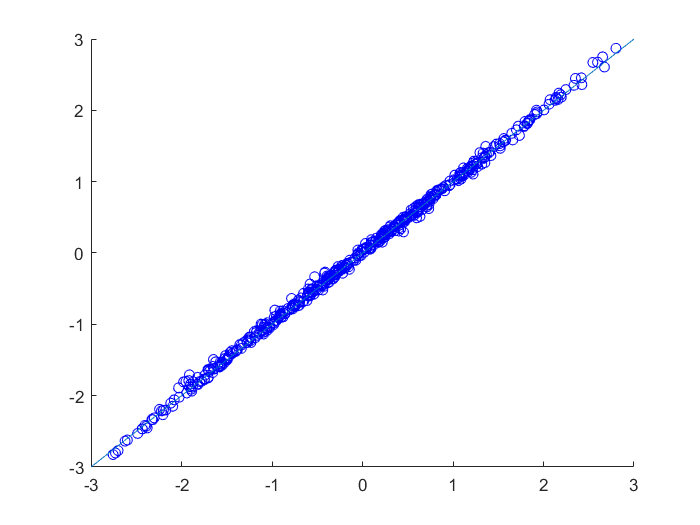

x = rand([500 1])*2*pi;
y = rand([500 1])*2*pi;
z = rand([500 1])*2 -1;

salidas = [];
deseado = [];
for i=1:500
    entrada = [x(i) y(i) z(i)];
    V1 = tanh(entrada*w_0+bias_0);
    V2 = tanh(V1*w_1+bias_1);
    %%salida = tanh(V2*w_2+bias_2)*4;
    salida = (V2*w_2+bias_2);
    
    y_deseado = sin(entrada(1)) + cos(entrada(2)) + entrada(3);
    salidas = [salidas salida];
    deseado = [deseado y_deseado];
end
figure()
hold on
plot(salidas, deseado,'ob')
plot(-3:3,-3:3)

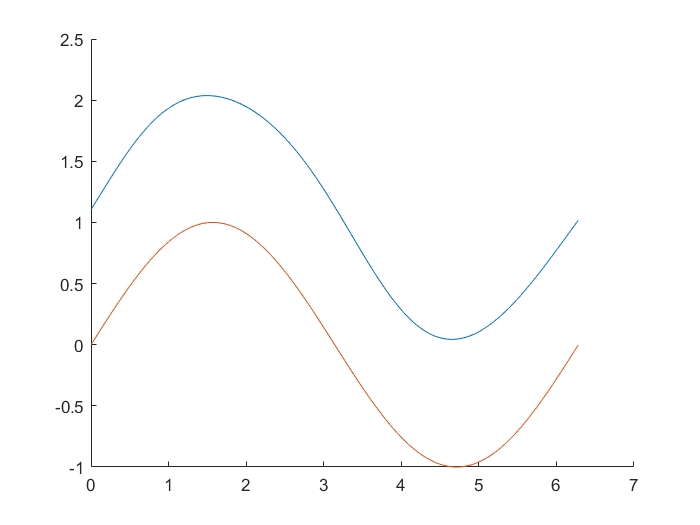

prueba_x = 0:0.01:2*pi;
for i = 1:length(prueba_x)
      V1 = tanh([prueba_x(i) 0 0]*w_0+bias_0);
      V2 = tanh(V1*w_1+bias_1);
      %%seno(i) = tanh(V2*w_2+bias_2)*3;
      seno(i) = V2*w_2+bias_2;
end
figure()
hold on
plot(prueba_x,seno )
plot(prueba_x, sin(prueba_x))

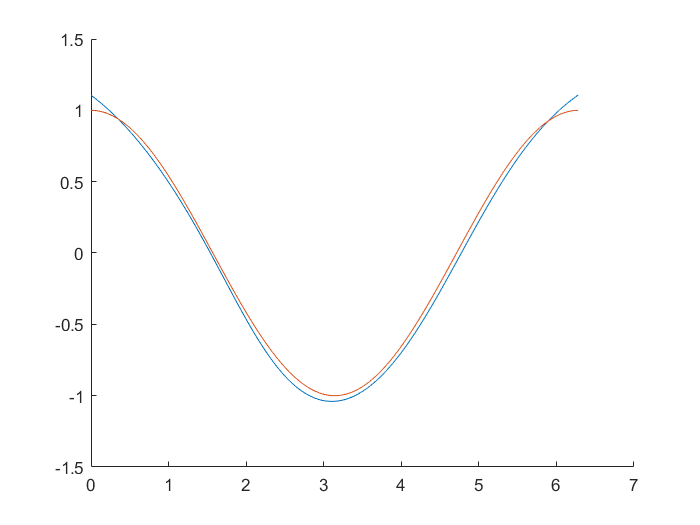

prueba_y = 0:0.01:2*pi;
for i = 1:length(prueba_y)
      V1 = tanh([0 prueba_y(i) 0]*w_0+bias_0);
      V2 = tanh(V1*w_1+bias_1);
      %%coseno(i) = tanh(V2*w_2+bias_2)*3;
      coseno(i) = V2*w_2+bias_2;
end
figure()
hold on
plot(prueba_y,coseno )
plot(prueba_y, cos(prueba_y))

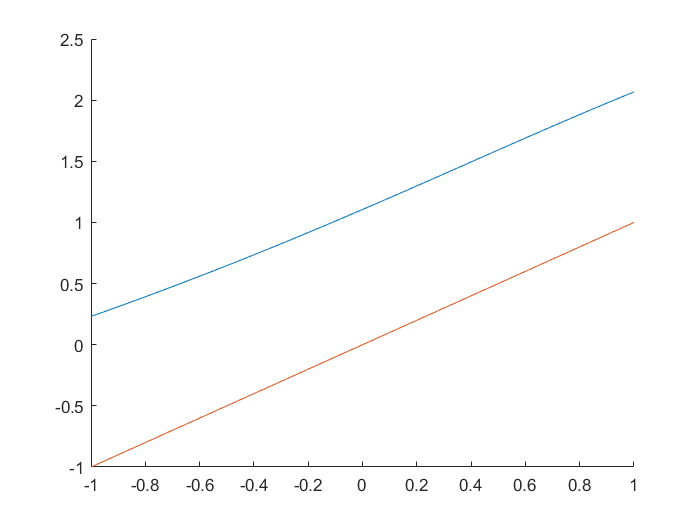

prueba_z = -1:0.01:1;
for i = 1:length(prueba_z)
      V1 = tanh([0 0 prueba_z(i)]*w_0+bias_0);
      V2 = tanh(V1*w_1+bias_1);
      %%lineal(i) = tanh(V2*w_2+bias_2)*3;
      lineal(i) = V2*w_2+bias_2;
end
figure()
hold on
plot(prueba_z,lineal )
plot(prueba_z, prueba_z)